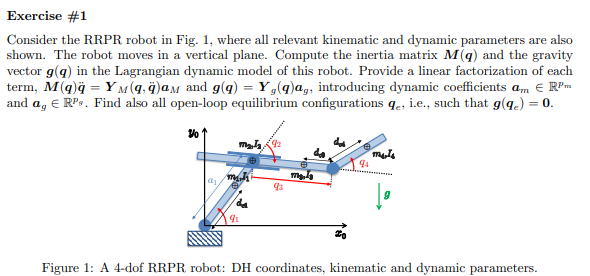

% This part is isolated from previous section
clear;clc

% syms k q1(t) q2(t) q3(t)
sigma = [1,1,0,1];
n = length(sigma);
% t = sym('t', 'real');
q = sym('q_', [n 1],'real');
q_d= sym('q_d_', [n 1],'real');
q_dot = sym('q_dot_', [n 1],'real');
q_ddot = sym('q_ddot_', [n 1],'real');
% 
dc = sym('dc_', [n 1],'real');
% k = sym('k', [n 1],'real');
l = sym('l_', [n 1],'real');
m = sym('m_', [n 1],'real');
% m_p = sym('m_p','real');
% m(2)=m(2)+m_p
I = sym('I_', [n 1],'real');
alpha_angle=sym('alpha','real')

$$alpha\_angle = \alpha$$

g0 = sym('g0','real');
g=[0,-g0,0]';
R2Robot=['rrpr';'xxxx';[1,1,1,1]]    

R2Robot = 3×4 char array
    'rrpr'
    'xxxx'
    ''


z = Gen_param(n);
z.sigmaD=R2Robot;
z.l=l;
z.q=q;
z.q_dot=q_dot;
z.dc=dc;
z.m=m;
z.I=I;
z.methodD=1

z = struct with fields:
                  sigmaD: [3×4 char]
                       l: [4×1 sym]
                      l_: []
                       q: [4×1 sym]
                   q_dot: [4×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [4×1 sym]
                       m: [4×1 sym]
                       I: [4×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 4
                  angle_: [1×4 sym]
               rcdefined: 1
                opt_expr: []
                collides: []
                joint_on: 1
                  xyonly: 0
    prismatic_CoM_method: [1 1 1 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_reference: 0
          

% z.dhTable=[]
z.firstParam='alpha';
% z.rc=[]
% z.movingframes=[]
z.angle_=sym(zeros(1,n));
z.opt_expr={[l(2),dc(2)],[0,0]};
% z.rcdefined=true;
z.joint_on=false;
z.prismatic_CoM_method(3)=2;

[Pc,vc,w,T,Ti,M] = getGenericPC2(z)

rcdefined = logical
   1


z = struct with fields:
                  sigmaD: [3×4 char]
                       l: [4×1 sym]
                      l_: []
                       q: [4×1 sym]
                   q_dot: [4×1 sym]
                      q_: []
                  q_dot_: []
                      dc: [4×1 sym]
                       m: [4×1 sym]
                       I: [4×1 sym]
                 methodD: 1
                 dhTable: []
              firstParam: 'alpha'
                       t: [1×1 sym]
                      rc: []
            movingframes: 0
                       n: 4
                  angle_: [1×4 sym]
               rcdefined: 1
                opt_expr: {[1×2 sym]  [0 0]}
                collides: []
                joint_on: 0
                  xyonly: 0
    prismatic_CoM_method: [1 1 2 1]
               dc_method: 0
                     g_q: []
                 isMotor: 0
                       g: []
            task_defined: {}
              xyx_offset: []
      global_q_referen

si falla aquí está el error


$$a = l_{1}$$

d = 0

$$a = l_{2}$$

d = 0

anglerot = 1×3 cell array
    {4×4 sym}    {4×4 sym}    {4×4 sym}


$$a = l_{4}$$

d = 0

method with PC , pay attention!
moving frames OFF!!


$$Ti = \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2}$$

moving frames OFF!!


$$Ti = \left(\begin{array}{cc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2}+\frac{{l_{1}}^{2}\,m_{2}\,{{\dot{q}}_{1}}^{2}}{2} \end{array}\right)$$

moving frames OFF!!


$$Ti = \left(\begin{array}{ccc} \frac{{{\dot{q}}_{1}}^{2}\,\left(m_{1}\,{{\mathrm{dc}}_{1}}^{2}+I_{1}\right)}{2} & \frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2}+\frac{{l_{1}}^{2}\,m_{2}\,{{\dot{q}}_{1}}^{2}}{2} & \frac{I_{3}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2}+\frac{m_{3}\,\left({{\dot{q}}_{2}}^{2}\,{\left({\mathrm{dc}}_{3}-q_{3}\right)}^{2}+{{\dot{q}}_{1}}^{2}\,\left({{\mathrm{dc}}_{3}}^{2}-2\,\cos\left(q_{2}\right)\,{\mathrm{dc}}_{3}\,l_{1}-2\,{\mathrm{dc}}_{3}\,q_{3}+{l_{1}}^{2}+2\,\cos\left(q_{2}\right)\,l_{1}\,q_{3}+{q_{3}}^{2}\right)+{{\dot{q}}_{3}}^{2}-{\dot{q}}_{1}\,{\dot{q}}_{2}\,\left(2\,{\mathrm{dc}}_{3}-2\,q_{3}\right)\,\left(q_{3}-{\mathrm{dc}}_{3}+l_{1}\,\cos\left(q_{2}\right)\right)+2\,l_{1}\,{\dot{q}}_{1}\,{\dot{q}}_{3}\,\sin\left(q_{2}\right)\right)}{2} \end{array}\right)$$

moving frames OFF!!


$$To\_derive = \begin{array}{l} \left(\begin{array}{cccc} -l_{1}\,\sin\left(q_{1}\left(t\right)\right)-\sigma_{1}-\sigma_{3} & -\sigma_{1}-\sigma_{3} & \cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right) & -\sigma_{1}\\ l_{1}\,\cos\left(q_{1}\left(t\right)\right)+\sigma_{2}+\sigma_{4} & \sigma_{2}+\sigma_{4} & \sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right) & \sigma_{2}\\ 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{4}\,\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)+q_{4}\left(t\right)\right)\\ \sigma_{2}=l_{4}\,\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)+q_{4}\left(t\right)\right)\\ \sigma_{3}=\sin\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\,q_{3}\left(t\right)\\ \sigma_{4}=\cos\left(q_{1}\left(t\right)+q_{2}\left(t\right)\right)\,q_{3}\left(t\right) \end{array}$$

$$q\_t = \left(\begin{array}{c} q_{1}\left(t\right)\\ q_{2}\left(t\right)\\ q_{3}\left(t\right)\\ q_{4}\left(t\right) \end{array}\right)$$

z_derivated = struct with fields:
    dot_t: [3×4 sym]


z_derivated = struct with fields:
     dot_t: [3×4 sym]
    ddot_t: [3×4 sym]


z_derivated = struct with fields:
     dot_t: [3×4 sym]
    ddot_t: [3×4 sym]
    tdot_t: [3×4 sym]


z_derivated = struct with fields:
        dot_t: [3×4 sym]
       ddot_t: [3×4 sym]
       tdot_t: [3×4 sym]
          dot: [3×4 sym]
    dot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3}\\ q_{4} & {\dot{q}}_{4} & {\ddot{q}}_{4} & {\dddot{q}}_{4} \end{array}\right)$$

z_derivated = struct with fields:
        dot_t: [3×4 sym]
       ddot_t: [3×4 sym]
       tdot_t: [3×4 sym]
          dot: [3×4 sym]
    dot_short: []


z_derivated = struct with fields:
         dot_t: [3×4 sym]
        ddot_t: [3×4 sym]
        tdot_t: [3×4 sym]
           dot: [3×4 sym]
     dot_short: []
          ddot: [3×4 sym]
    ddot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3}\\ q_{4} & {\dot{q}}_{4} & {\ddot{q}}_{4} & {\dddot{q}}_{4} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×4 sym]
        ddot_t: [3×4 sym]
        tdot_t: [3×4 sym]
           dot: [3×4 sym]
     dot_short: []
          ddot: [3×4 sym]
    ddot_short: []


z_derivated = struct with fields:
         dot_t: [3×4 sym]
        ddot_t: [3×4 sym]
        tdot_t: [3×4 sym]
           dot: [3×4 sym]
     dot_short: []
          ddot: [3×4 sym]
    ddot_short: []
          tdot: [3×4 sym]
    tdot_short: []


$$new\_dep\_var = \left(\begin{array}{cccc} q_{1} & {\dot{q}}_{1} & {\ddot{q}}_{1} & {\dddot{q}}_{1}\\ q_{2} & {\dot{q}}_{2} & {\ddot{q}}_{2} & {\dddot{q}}_{2}\\ q_{3} & {\dot{q}}_{3} & {\ddot{q}}_{3} & {\dddot{q}}_{3}\\ q_{4} & {\dot{q}}_{4} & {\ddot{q}}_{4} & {\dddot{q}}_{4} \end{array}\right)$$

z_derivated = struct with fields:
         dot_t: [3×4 sym]
        ddot_t: [3×4 sym]
        tdot_t: [3×4 sym]
           dot: [3×4 sym]
     dot_short: []
          ddot: [3×4 sym]
    ddot_short: []
          tdot: [3×4 sym]
    tdot_short: []


$$Pc = \left(\begin{array}{cccc} {\mathrm{dc}}_{1}\,\cos\left(q_{1}\right) & l_{1}\,\cos\left(q_{1}\right) & l_{1}\,\cos\left(q_{1}\right)-\cos\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{3}-q_{3}\right) & q_{3}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+{\mathrm{dc}}_{4}\,\cos\left(q_{1}+q_{2}+q_{4}\right)\\ {\mathrm{dc}}_{1}\,\sin\left(q_{1}\right) & l_{1}\,\sin\left(q_{1}\right) & l_{1}\,\sin\left(q_{1}\right)-\sin\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{3}-q_{3}\right) & q_{3}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)+{\mathrm{dc}}_{4}\,\sin\left(q_{1}+q_{2}+q_{4}\right)\\ 0 & 0 & 0 & 0 \end{array}\right)$$

$$vc = \begin{array}{l} \left(\begin{array}{cccc} -{\mathrm{dc}}_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right) & -l_{1}\,{\dot{q}}_{1}\,\sin\left(q_{1}\right) & \sigma_{3}+{\dot{q}}_{1}\,\left(\sin\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{3}-q_{3}\right)-l_{1}\,\sin\left(q_{1}\right)\right)+{\dot{q}}_{2}\,\sin\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{3}-q_{3}\right) & \sigma_{3}-{\dot{q}}_{1}\,\left(\sigma_{2}+l_{1}\,\sin\left(q_{1}\right)+{\mathrm{dc}}_{4}\,\sigma_{5}\right)-{\dot{q}}_{2}\,\left(\sigma_{2}+{\mathrm{dc}}_{4}\,\sigma_{5}\right)-{\mathrm{dc}}_{4}\,{\dot{q}}_{4}\,\sigma_{5}\\ {\mathrm{dc}}_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right) & l_{1}\,{\dot{q}}_{1}\,\cos\left(q_{1}\right) & \sigma_{1}-{\dot{q}}_{1}\,\left(\cos\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{3}-q_{3}\right)-l_{1}\,\cos\left(q_{1}\right)\right)-{\dot{q}}_{2}\,\cos\left(q_{1}+q_{2}\right)\,\left({\mathrm{dc}}_{3}-q_{3}\right) & {\dot{q}}_{1}\,\left(\sigma_{4}+l_{1}\,\cos\left(q_{1}\right)+{\mathrm{dc}}_{4}\,\sigma_{6}\right)+{\dot{q}}_{2}\,\left(\sigma_{4}+{\mathrm{dc}}_{4}\,\sigma_{6}\right)+\sigma_{1}+{\mathrm{dc}}_{4}\,{\dot{q}}_{4}\,\sigma_{6}\\ 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}={\dot{q}}_{3}\,\sin\left(q_{1}+q_{2}\right)\\ \sigma_{2}=q_{3}\,\sin\left(q_{1}+q_{2}\right)\\ \sigma_{3}={\dot{q}}_{3}\,\cos\left(q_{1}+q_{2}\right)\\ \sigma_{4}=q_{3}\,\cos\left(q_{1}+q_{2}\right)\\ \sigma_{5}=\sin\left(q_{1}+q_{2}+q_{4}\right)\\ \sigma_{6}=\cos\left(q_{1}+q_{2}+q_{4}\right) \end{array}$$

$$w = \left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ {\dot{q}}_{1} & {\dot{q}}_{1}+{\dot{q}}_{2} & {\dot{q}}_{1}+{\dot{q}}_{2} & {\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{4} \end{array}\right)$$

$$M = \begin{array}{l} \left(\begin{array}{cccc} I_{1}+I_{2}+I_{3}+I_{4}+{{\mathrm{dc}}_{1}}^{2}\,m_{1}+{{\mathrm{dc}}_{3}}^{2}\,m_{3}+{{\mathrm{dc}}_{4}}^{2}\,m_{4}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{3}+{l_{1}}^{2}\,m_{4}+m_{3}\,{q_{3}}^{2}+m_{4}\,{q_{3}}^{2}-2\,{\mathrm{dc}}_{3}\,m_{3}\,q_{3}+2\,{\mathrm{dc}}_{4}\,l_{1}\,m_{4}\,\cos\left(q_{2}+q_{4}\right)-2\,{\mathrm{dc}}_{3}\,l_{1}\,m_{3}\,\cos\left(q_{2}\right)+\sigma_{5}+2\,l_{1}\,m_{3}\,q_{3}\,\cos\left(q_{2}\right)+2\,l_{1}\,m_{4}\,q_{3}\,\cos\left(q_{2}\right) & \sigma_{2} & \sigma_{4} & \sigma_{3}\\ \sigma_{2} & I_{2}+I_{3}+I_{4}+{{\mathrm{dc}}_{3}}^{2}\,m_{3}+{{\mathrm{dc}}_{4}}^{2}\,m_{4}+m_{3}\,{q_{3}}^{2}+m_{4}\,{q_{3}}^{2}-2\,{\mathrm{dc}}_{3}\,m_{3}\,q_{3}+\sigma_{5} & \sigma_{7} & \sigma_{1}\\ \sigma_{4} & \sigma_{7} & m_{3}+m_{4} & \sigma_{7}\\ \sigma_{3} & \sigma_{1} & \sigma_{7} & m_{4}\,{{\mathrm{dc}}_{4}}^{2}+I_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{4}\,{{\mathrm{dc}}_{4}}^{2}+m_{4}\,q_{3}\,\cos\left(q_{4}\right)\,{\mathrm{dc}}_{4}+I_{4}\\ \sigma_{2}=I_{2}+I_{3}+I_{4}+{{\mathrm{dc}}_{3}}^{2}\,m_{3}+{{\mathrm{dc}}_{4}}^{2}\,m_{4}+m_{3}\,{q_{3}}^{2}+m_{4}\,{q_{3}}^{2}-2\,{\mathrm{dc}}_{3}\,m_{3}\,q_{3}+\sigma_{6}-{\mathrm{dc}}_{3}\,l_{1}\,m_{3}\,\cos\left(q_{2}\right)+\sigma_{5}+l_{1}\,m_{3}\,q_{3}\,\cos\left(q_{2}\right)+l_{1}\,m_{4}\,q_{3}\,\cos\left(q_{2}\right)\\ \sigma_{3}=I_{4}+{{\mathrm{dc}}_{4}}^{2}\,m_{4}+\sigma_{6}+{\mathrm{dc}}_{4}\,m_{4}\,q_{3}\,\cos\left(q_{4}\right)\\ \sigma_{4}=l_{1}\,m_{3}\,\sin\left(q_{2}\right)+\sigma_{7}+l_{1}\,m_{4}\,\sin\left(q_{2}\right)\\ \sigma_{5}=2\,{\mathrm{dc}}_{4}\,m_{4}\,q_{3}\,\cos\left(q_{4}\right)\\ \sigma_{6}={\mathrm{dc}}_{4}\,l_{1}\,m_{4}\,\cos\left(q_{2}+q_{4}\right)\\ \sigma_{7}=-{\mathrm{dc}}_{4}\,m_{4}\,\sin\left(q_{4}\right) \end{array}$$

[C,cac,Csubs,S] = getCs(M,z.q,z.q_dot)

>> Getting  the Christoffel’sym. Might take a while...


C = 1×4 cell array
    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}


$$cac = \begin{array}{l} \left(\begin{array}{c} \sigma_{4}+2\,l_{1}\,{\dot{q}}_{3}\,\cos\left(q_{2}\right)\,\left(m_{3}+m_{4}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)+\sigma_{1}-l_{1}\,{\dot{q}}_{2}\,\sin\left(q_{2}\right)\,\left(2\,{\dot{q}}_{1}+{\dot{q}}_{2}\right)\,\sigma_{5}-\sigma_{2}-{\mathrm{dc}}_{4}\,l_{1}\,m_{4}\,\sin\left(q_{2}+q_{4}\right)\,\left({\dot{q}}_{2}+{\dot{q}}_{4}\right)\,\left(2\,{\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{4}\right)\\ \sigma_{4}+l_{1}\,{{\dot{q}}_{1}}^{2}\,\sin\left(q_{2}\right)\,\sigma_{5}+\sigma_{3}+\sigma_{1}-\sigma_{2}\\ -{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}\,\sigma_{5}-{\mathrm{dc}}_{4}\,m_{4}\,\cos\left(q_{4}\right)\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}+{\dot{q}}_{4}\right)}^{2}-l_{1}\,{{\dot{q}}_{1}}^{2}\,\cos\left(q_{2}\right)\,\left(m_{3}+m_{4}\right)\\ \sigma_{3}+{\mathrm{dc}}_{4}\,m_{4}\,q_{3}\,\sin\left(q_{4}\right)\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}+\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,{\mathrm{dc}}_{4}\,m_{4}\,{\dot{q}}_{3}\,\cos\left(q_{4}\right)\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)\\ \sigma_{2}={\mathrm{dc}}_{4}\,m_{4}\,q_{3}\,{\dot{q}}_{4}\,\sin\left(q_{4}\right)\,\left(2\,{\dot{q}}_{1}+2\,{\dot{q}}_{2}+{\dot{q}}_{4}\right)\\ \sigma_{3}={\mathrm{dc}}_{4}\,l_{1}\,m_{4}\,{{\dot{q}}_{1}}^{2}\,\sin\left(q_{2}+q_{4}\right)\\ \sigma_{4}=2\,{\dot{q}}_{3}\,\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)\,\sigma_{5}\\ \sigma_{5}=m_{3}\,q_{3}-{\mathrm{dc}}_{3}\,m_{3}+m_{4}\,q_{3} \end{array}$$

Csubs = 1×4 cell array
    {4×4 sym}    {4×4 sym}    {4×4 sym}    {4×4 sym}


isMotor=false

isMotor = logical
   0


[g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, z.q, l, m, dc, z.g, isMotor)

M

$$M = \begin{array}{l} \left(\begin{array}{cccc} I_{1}+I_{2}+I_{3}+I_{4}+{{\mathrm{dc}}_{1}}^{2}\,m_{1}+{{\mathrm{dc}}_{3}}^{2}\,m_{3}+{{\mathrm{dc}}_{4}}^{2}\,m_{4}+{l_{1}}^{2}\,m_{2}+{l_{1}}^{2}\,m_{3}+{l_{1}}^{2}\,m_{4}+m_{3}\,{q_{3}}^{2}+m_{4}\,{q_{3}}^{2}-2\,{\mathrm{dc}}_{3}\,m_{3}\,q_{3}+2\,{\mathrm{dc}}_{4}\,l_{1}\,m_{4}\,\cos\left(q_{2}+q_{4}\right)-2\,{\mathrm{dc}}_{3}\,l_{1}\,m_{3}\,\cos\left(q_{2}\right)+\sigma_{5}+2\,l_{1}\,m_{3}\,q_{3}\,\cos\left(q_{2}\right)+2\,l_{1}\,m_{4}\,q_{3}\,\cos\left(q_{2}\right) & \sigma_{2} & \sigma_{4} & \sigma_{3}\\ \sigma_{2} & I_{2}+I_{3}+I_{4}+{{\mathrm{dc}}_{3}}^{2}\,m_{3}+{{\mathrm{dc}}_{4}}^{2}\,m_{4}+m_{3}\,{q_{3}}^{2}+m_{4}\,{q_{3}}^{2}-2\,{\mathrm{dc}}_{3}\,m_{3}\,q_{3}+\sigma_{5} & \sigma_{7} & \sigma_{1}\\ \sigma_{4} & \sigma_{7} & m_{3}+m_{4} & \sigma_{7}\\ \sigma_{3} & \sigma_{1} & \sigma_{7} & m_{4}\,{{\mathrm{dc}}_{4}}^{2}+I_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=m_{4}\,{{\mathrm{dc}}_{4}}^{2}+m_{4}\,q_{3}\,\cos\left(q_{4}\right)\,{\mathrm{dc}}_{4}+I_{4}\\ \sigma_{2}=I_{2}+I_{3}+I_{4}+{{\mathrm{dc}}_{3}}^{2}\,m_{3}+{{\mathrm{dc}}_{4}}^{2}\,m_{4}+m_{3}\,{q_{3}}^{2}+m_{4}\,{q_{3}}^{2}-2\,{\mathrm{dc}}_{3}\,m_{3}\,q_{3}+\sigma_{6}-{\mathrm{dc}}_{3}\,l_{1}\,m_{3}\,\cos\left(q_{2}\right)+\sigma_{5}+l_{1}\,m_{3}\,q_{3}\,\cos\left(q_{2}\right)+l_{1}\,m_{4}\,q_{3}\,\cos\left(q_{2}\right)\\ \sigma_{3}=I_{4}+{{\mathrm{dc}}_{4}}^{2}\,m_{4}+\sigma_{6}+{\mathrm{dc}}_{4}\,m_{4}\,q_{3}\,\cos\left(q_{4}\right)\\ \sigma_{4}=l_{1}\,m_{3}\,\sin\left(q_{2}\right)+\sigma_{7}+l_{1}\,m_{4}\,\sin\left(q_{2}\right)\\ \sigma_{5}=2\,{\mathrm{dc}}_{4}\,m_{4}\,q_{3}\,\cos\left(q_{4}\right)\\ \sigma_{6}={\mathrm{dc}}_{4}\,l_{1}\,m_{4}\,\cos\left(q_{2}+q_{4}\right)\\ \sigma_{7}=-{\mathrm{dc}}_{4}\,m_{4}\,\sin\left(q_{4}\right) \end{array}$$

Pc(:,4)

$$ans = \left(\begin{array}{c} q_{3}\,\cos\left(q_{1}+q_{2}\right)+l_{1}\,\cos\left(q_{1}\right)+{\mathrm{dc}}_{4}\,\cos\left(q_{1}+q_{2}+q_{4}\right)\\ q_{3}\,\sin\left(q_{1}+q_{2}\right)+l_{1}\,\sin\left(q_{1}\right)+{\mathrm{dc}}_{4}\,\sin\left(q_{1}+q_{2}+q_{4}\right)\\ 0 \end{array}\right)$$

Ti(:,2)

$$ans = \frac{I_{2}\,{\left({\dot{q}}_{1}+{\dot{q}}_{2}\right)}^{2}}{2}+\frac{{l_{1}}^{2}\,m_{2}\,{{\dot{q}}_{1}}^{2}}{2}$$

% g_q

## torque regulation catesian

% % z_regulation_torque=Join_Torque_Control_Law_Regulation(z)
% 

## using Cartesian dynamics control LAw

% 
% % z_regulation_torque=cartesian_dynamics_Control_Law_Regulation(z)
% 

## dynamic model computation neccessary for the control law

% % z.task_defined={struct('Pc',q(1)+q(2),'f',sum([q(1),q(2),0]))} %pc is note necessary
% % z.taskpositions=struct('main',2,'remain',[1])
% pd={sym('pd_1_',[1,1],'real'),sym('pd_2_',[2,1],'real')};
% z.task_defined={struct('f',sum([q(1),q(2),0]),'pd_',pd{1},'pd_dot_',[0]),struct('f','end_effector','pd_',pd{2},'pd_dot_',[0.1,-0.5]')} %pc is note necessary
% z.xyonly=false %% should be false if we wnat to add new tasks
% [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot,PC_EE]= getGenericPC_EE2(z);
% PCVar.f_dot
% PCVar.f_ddot
% PCVar.f_tdot
% PC_EEShort.J
% % f(3)=
% % xyonly=true
% % [f,J,V,J_ps,PCVar,PC_EEShort,VarShortRobot]= getGenericPC_EE(R2Robot,l,q,qd,dc,m,I,xyonly)
% % VarShortRobot.M
% % angle_desired=[0,0]
% % l(1)=0
% % [Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z);
% % Trans.Jacobian_PTotal
% % Trans.Jacobian_dot_PTotal
% % [C,cac,Csubs,S] = getCs(M,q,q_dot);
% % cac

## rank of J

% rank(J)

% rd_1=f(1,:)
% rd_2=f(2:end,:)

## redundancy task with prioriy

% replace_values=true
% % vars2replace=[z.q;z_q_dot_k,z.]
% z.q_=[0,pi/2,-pi/2]'
% 
% [q_dot_k,z_task] = Redundancy_tasks_with_Priority(z,PC_EE,replace_values);
% 

## seein varaibles

% q_dot_k{:}
% z_task.J_k{:}
% z_task.J_k_pinv{:}
% z_task.P_A_k{:}
% 
% z_task.q_dot_k_{:}
% z_task.J_k_{:}
% z_task.J_k_pinv_{:}
% z_task.P_A_k_{:}

% r_dot_k=z_task.r_dot_k
% simplify(subs(q_dot_k{2},r_dot_k{1},0))
% simplify(simplify(pinv((z_task.J_k{2}*z_task.P_A_k{1})))*z_task.r_dot_k{2})
% 

## cheking if is possible do both tasks

% f_k_red=simplify(subs(z_task.f_k{2},q(1)+q(2),pi/2))
% q_red=[q(1),q(3)]'
% q_dot_red=[q_dot(1),q_dot(3)]'
% J_k_red=jacobian(f_k_red,q_red)
% q_dot_=q_dot;
% q_dot_(2)=-q_dot_(1)

## singularities

% simplify(det(J_k_red)) %%singular in q_1-q_3=m*pi/2 where m>0

## replacing values

% q_=[0,pi/2,-pi/2]'
% l_=[0.5,0.5,0.5]'
% r_dot_k=[z_task.r_dot_k{1};z_task.r_dot_k{2}]
% r_dot_k_=[0,0.1,-0.5]'
% vars2replace =[q ;l;r_dot_k]
% vars2replace_=[q_;l_;r_dot_k_]
% q_dot_k{2}
% q_dot_k_=subs(z_task.q_dot_k_{2},vars2replace,vars2replace_)
% term1_=subs(z_task.J_k{2}*z_task.P_A_k{1},vars2replace,vars2replace_)
% pinv(term1_)

## replacing singular values into each jacobian

% z_task.J_k{1}*q_dot_k_ %% equal to zero it means that the task can be done
% 
% subs(z_task.J_k{2}*q_dot_k_,[q;l],[q_;l_] )%% in this case it is different of the pd_dot_2 then this task s not possible to realize only with an minimization error result


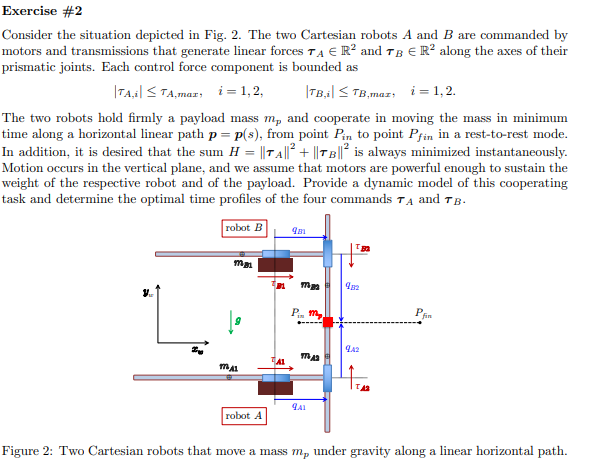

% % This part is isolated from previous section
% clear;clc;
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [0,0]; %% rot=0 prismatic=1
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q', [n 1],'real');
% q_d= sym('q_d', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% % 
% dc = sym('dc', [n 1],'real');
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% m_p = sym('m_p','real');
% % m(2)=m(2)+m_p;
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real');
% g0 = sym('g0','real');
% 
% R2Robot=['pp';'xy';[1,1]]    
% 
% z = Gen_param(n);
% z.g=[0,-g0,0]';
% z.sigmaD=R2Robot;
% z.l=l;
% z.q=q;
% z.q_dot=q_dot;
% z.q_ddot = q_ddot ;
% z.dc=dc;
% z.m=m;
% z.I=I;
% z.methodD=1;
% % z.dhTable=[]
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% 
% %  z.opt_expr={[l(1),dc(1)],[0,0]};
% % z.rcdefined=true;

% [Pc,vc,w,T,Ti,M] = getGenericPC2(z)
% [C,cac,Csubs,S] = getCs(M,z.q,z.q_dot)

% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l, m, dc, z.g, isMotor)

% M
% Pc
% g_q

%  u_subs = M*z.q_ddot +S*z.q+g_q
%  

## Continued by hand

## 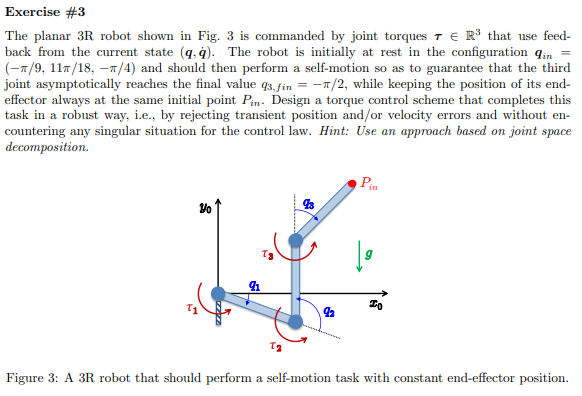

% clear all, clc, close all
% % This part is isolated from previous sectionclear;clc
% 
% % syms k q1(t) q2(t) q3(t)
% sigma = [1,1,1];
% R2Robot=['rrr';'xxx';sigma]    
% n = length(sigma);
% % t = sym('t', 'real');
% q = sym('q_', [n 1],'real');
% q_d= sym('q_d_', [n 1],'real');
% q_dot = sym('q_dot_', [n 1],'real');
% q_ddot = sym('q_ddot_', [n 1],'real');
% % 
% dc = sym('dc', [n 1],'real');
% % dc(6)=dc(6)
% % k = sym('k', [n 1],'real');
% l = sym('l', [n 1],'real');
% m = sym('m', [n 1],'real');
% 
% m_p = sym('m_p','real');
% d = sym('d','real');
% %m(2)=m(2)+m_p
% I = sym('I', [n 1],'real');
% alpha_angle=sym('alpha','real')
% g0 = sym('g0','real');
% % g=[-g0*sin(alpha_angle),-g0*cos(alpha_angle),0]';
% % g=[0,-g0*sin(alpha_angle),0]';
% 
% 
% z = Gen_param(n);
% z.g=[0,-g0,0]';
% z.sigmaD=R2Robot;
% 
% z.q=q;
% z.q_dot=q_dot;
% z.q_ddot =q_ddot;
% z.dc=dc;
% 
% z.I=I;
% z.methodD=1%with DH tablemethod=2, other case method=1
% % z.dhTable=dhTable
% z.firstParam='alpha';
% % z.rc=[]
% % z.movingframes=[]
% z.angle_=sym(zeros(1,n));
% z.l=l;
% z.m=m;
% % z.opt_expr={[l(1),dc'],[0,0,d]};
% % z.rcdefined=true;
% % z.prismatic_CoM_method=[1,2];1%% normal mode onle CoM=dc(i) in %% 2 inverse mdoe CoM=q(i)-dc(i) %% for the moment only for prismatics

## computing M

% [Pc,vc,w,T,Ti,M,VarShortRobot,Trans] = getGenericPC2(z);
% [C,cac,Csubs,S] = getCs(M,q,q_dot);
% isMotor=false
% [g_q, PE, U,g_q_short,PE_short] = getGravityWithPc(Pc, q, l, m, dc, z.g, isMotor)

% 
% % T
% % Ti(:)
% Trans.PTotal
% Trans.Jacobian_PTotal
% Pc
% M
% S
% g_q
% % cac
% % % [C,cac,Csubs] = getCs(Msubs,q',qd')
% tau =simplify( M*z.q_ddot + cac+g_q);
% % 
% tau
% % tau_=subs(tau)

% % C{:}
% % R=sym('R','real')
% % vars2replace =[q(2);q_dot(1)]
% % vars2replace_=[R;0]
% % tau_=subs(tau,vars2replace,vars2replace_)

## computing maximun aceleration

% clear all;
% close all;
% clc;
% m_=10
% l_=2
% theta_T=pi;
% theta_s_=theta_T/6
% I_=m_*l_^2/12
% g_0=9.81
% d_=l_/2
% tau_g_max_=m_*g_0*d_
% tau_max_=200
% sin(theta_s_)
% T_min=sqrt(16*I_*pi/(3*(tau_max_-tau_g_max_*sin(theta_s_))))

## bang cost bang profile

% T=sym('T','real');
% V1=sym('V1','real');
% A1=sym('A1','real');
% T_=1*T_min%1.2165;
% % T_=1.2165;
% Ts_=T_/4
% A1_=16*pi/(3*T_^2);
% Ts=T/4;
% V1=Ts*A1;
% V1_=Ts_*A1_;
% qA=[0,1]'
% qB_=[pi,pi]'
% qB=sym('qB',[2,1],'real');
% 
% I_0=1
% % [qa_piece2,T_,Ts_,t] = BangcostBangPRofile(qA(1,1),qB(1,1),V1_, A1_,T_)
% [qa_piece2,T_,Ts_,t] = BangcostBangPRofile(qA(1,1),qB(1,1),V1_, A1_,T_)
% fplot(qa_piece2(1,:),[0,T_])
% figure
% fplot(qa_piece2(2,:),[0,T_])
% figure
% fplot(qa_piece2(3,:),[0,T_])
% figure
% % [qa_piece2,T_,Ts_] = BangcostBangPRofile(qA(1,1),qB(1,1),V1_, A1_,T_)
% % tau_2=int(qa_piece2,t)

## tau 2

% tau_func=I_*qa_piece2(1,:)+tau_g_max_*sin(qa_piece2(3,:))
% fplot(tau_func,[0,T_])
% % figure
% % fplot(qa_piece2(2,:),[0,T_])
% % figure
% % fplot(qa_piece2(3,:),[0,T_])